# **TASK 4)**

# **4.1.a)**

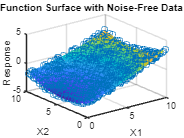

% generating and visualizing a two-dimensional noise-free dataset
clear ;
% Generate noise-free data
N = 1000; % number of data points for visualization
[X, y] = twoDimData1(N, 0); 

% Visualize the true function
[xq, yq] = meshgrid(0:0.2:10, 0:0.2:10); % grid for the x and y axis
vq = griddata(X(:, 1), X(:, 2), y, xq, yq); % Interpolate the function values on the grid points
mesh(xq, yq, vq); % Plotting the function as a surface

hold on;
plot3(X(:, 1), X(:, 2), y, 'o'); % Overlay noise-free data points
xlabel('X1');
ylabel('X2');
zlabel('Response');
title('True Function Surface with Noise-Free Data Points');
hold off;

# **4.1.b)**

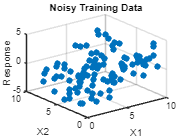

%extending the previous setup by 
%introducing noise into the training and validation datasets
noise_variance = 1; % Specified noise level
train_N = 100; % Number of training data points
val_N = 1000; % Number of validation data points for evaluation

% Generate noisy training data
[X_train, y_train] = twoDimData1(train_N, noise_variance);

% Generate a noisy validation set
[X_val, y_val] = twoDimData1(val_N, noise_variance);

% Optionally visualize the noisy training data
figure;
scatter3(X_train(:, 1), X_train(:, 2), y_train, 'filled');
hold on;
title('Noisy Training Data');
xlabel('X1');
ylabel('X2');
zlabel('Response');
grid on;

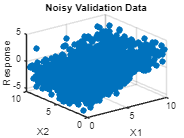


% Optionally visualize the noisy validation data
figure;
scatter3(X_val(:, 1), X_val(:, 2), y_val, 'filled');
title('Noisy Validation Data');
xlabel('X1');
ylabel('X2');
zlabel('Response');
grid on;

# **4.1.c)**

%fitting a linear regression model to the noisy training data and 
%evaluating its performance on the noisy validation data

% fit lr to the training data
linear_model = LinRegress(X_train, y_train);

% Evaluate the linear model on the validation set
y_pred_val_linear = evalModel(linear_model, X_val);
mse_val_linear = mean((y_val - y_pred_val_linear).^2);

% Output the MSE for the linear regression model
fprintf('MSE for Linear Regression: %.4f\n', mse_val_linear);

MSE for Linear Regression: 2.8360


# **4.1.d)**

%assessing polynomial regression models of various 
% degrees to determine which degree provides the best fit for the data

% Define polynomial degrees to test
poly_degrees = 2:5;

% Preallocate array for storing MSE values
mse_values_poly = zeros(length(poly_degrees), 1);

% Fit polynomial models and calculate MSE
for i = 1:length(poly_degrees)
    degree = poly_degrees(i);
    
    % Generate polynomial features
    [X_poly_train, ~] = poly_x2(X_train, degree);
    [X_poly_val, ~] = poly_x2(X_val, degree);
    
    % Fit polynomial regression model
    poly_model = polyfit(X_train, y_train, 0, degree); % No regularization
    
    % Evaluate the polynomial model on the validation set
    y_pred_val_poly = evalModel(poly_model, X_poly_val);
    mse_values_poly(i) = mean((y_val - y_pred_val_poly).^2);
end

% Output the MSE for each polynomial degree
for i = 1:length(poly_degrees)
    fprintf('MSE for Polynomial Degree %d: %.4f\n', poly_degrees(i), mse_values_poly(i));
end

MSE for Polynomial Degree 2: 1.0466
MSE for Polynomial Degree 3: 1.1245
MSE for Polynomial Degree 4: 1.1616
MSE for Polynomial Degree 5: 1.2373



[best_mse_poly, best_degree_idx] = min(mse_values_poly);
best_degree_poly = poly_degrees(best_degree_idx);

% Output the best degree and its MSE
fprintf('Best degree for Polynomial Regression: %d with MSE: %.4f\n', best_degree_poly, best_mse_poly);

Best degree for Polynomial Regression: 2 with MSE: 1.0466


# **4.1.e)**

%comparing poly and best found knn

k_values = 1:20; % Range of k values to test for KNN
mse_values_knn = zeros(length(k_values), 1);
for i = 1:length(k_values)
    k = k_values(i);
    knn_model = knnRegress(X_train, y_train, k);
    y_pred_knn = evalModel(knn_model, X_val);
    mse_values_knn(i) = mean((y_val - y_pred_knn).^2);
end

% k value with smallest MSE
[best_mse_knn, best_k_idx] = min(mse_values_knn);
best_k = k_values(best_k_idx);
fprintf('Best k for KNN: %d with MSE: %.4f\n', best_k, best_mse_knn);

Best k for KNN: 8 with MSE: 1.2778



if best_mse_knn < best_mse_poly
    fprintf('KNN model is better than the polynomial model with MSE: %.4f\n', best_mse_knn);
else
    fprintf('Polynomial model is better than the KNN model with MSE: %.4f\n', best_mse_poly);
end

Polynomial model is better than the KNN model with MSE: 1.0466


# **4.2.a)**

%number of regressors required for linear and polynomial 
% (up to degree 3) regression models in a 10-dimensional dataset

clearvars -except best_mse_poly;
num_dimensions = 10;

% regressors for linear regression
num_regressors_linear = num_dimensions + 1; % Including the intercept
num_regressors_poly = 1; % Starting with the intercept term

% Linear terms
num_regressors_poly = num_regressors_poly + num_dimensions;

% Quadratic terms (squared and cross-product terms)
num_regressors_poly = num_regressors_poly + num_dimensions + nchoosek(num_dimensions, 2);

% Cubic terms (cubed, squared-cross-product, and cross-product of three different features)
num_regressors_poly = num_regressors_poly + num_dimensions + (num_dimensions * (num_dimensions - 1)) + nchoosek(num_dimensions, 3);

fprintf('Number of regressors for linear regression: %d\n', num_regressors_linear);

Number of regressors for linear regression: 11


fprintf('Number of regressors for polynomial regression up to degree 3: %d\n', num_regressors_poly);

Number of regressors for polynomial regression up to degree 3: 286


# **4.2.b)**

%Generates noisy training and validation datasets for subsequent model evaluations

noise_variance = 1; 
train_N = 1000; % training data points
val_N = 10000; % validation data points

% noisy training data
[X_train, y_train] = tenDimData(train_N, noise_variance);

% noisy validation data
[X_val, y_val] = tenDimData(val_N, noise_variance);

# **4.2.c)**

%Fits a linear regression model to the training data and 
% evaluates it on the validation dataset.


% Fitting linear regress to training data
linear_model = LinRegress(X_train, y_train);

% Evaluatiion
y_pred_val_linear = evalModel(linear_model, X_val);
mse_val_linear = mean((y_val - y_pred_val_linear).^2);

fprintf('MSE for Linear Regression on Validation Set: %.4f\n', mse_val_linear);

MSE for Linear Regression on Validation Set: 1.2250


# **4.2.d)**

%Extends the model evaluation to polynomial regression, considering up to the third degree.


% training and validation data to polynom of degree 3
[X_poly_train, ~] = poly_x2(X_train, 3);
[X_poly_val, ~] = poly_x2(X_val, 3);

% Fit polynomial regression model to the training data
poly_model_degree_3 = LinRegress(X_poly_train, y_train);

% number of regressors matches the calculated number
assert(size(X_poly_train, 2) == num_regressors_poly, 'Number of regressors does not match the calculation.');

% Evaluatiion
y_pred_val_poly = evalModel(poly_model_degree_3, X_poly_val);
mse_val_poly = mean((y_val - y_pred_val_poly).^2);

fprintf('MSE for Polynomial Regression (degree 3) on Validation Set: %.4f\n', mse_val_poly);

MSE for Polynomial Regression (degree 3) on Validation Set: 1.4425


# **4.2.e)**

%Investigates the effect of regularization on polynomial regression 
% to mitigate potential overfitting


regularization_lambdas = [0.001, 0.01, 0.1, 1, 10, 20, 30, 40, 60, 80, 100];
mse_values_regul = zeros(length(regularization_lambdas), 1);

for i = 1:length(regularization_lambdas)
    lambda = regularization_lambdas(i);
    
    % Fit with regularization
    poly_model_regul = LinRegressRegul(X_poly_train, y_train, lambda);
    
    % Evaluation
    y_pred_val_regul = evalModel(poly_model_regul, X_poly_val);
    mse_values_regul(i) = mean((y_val - y_pred_val_regul).^2);
end

% Find the regularization strength with the smallest MSE
[best_mse_regul, best_lambda_idx] = min(mse_values_regul);
best_lambda = regularization_lambdas(best_lambda_idx);

fprintf('Best regularization lambda for Polynomial Regression: %f with MSE: %.4f\n', best_lambda, best_mse_regul);

Best regularization lambda for Polynomial Regression: 20.000000 with MSE: 1.0485


# **4.2.f)**

%Compares the performance of KNN models across a range of k values 
%and contrasts the best KNN model with the best polynomial model.

% Range of k values to test
k_values = 1:20;

% Preallocate array for MSE values of KNN models
mse_values_knn = zeros(length(k_values), 1);

% Loop over k values to train KNN models and calculate MSE on validation data
for i = 1:length(k_values)
    k = k_values(i);
    
    % Train KNN model
    knn_model = knnRegress(X_train, y_train, k);
    
    % Evaluate the KNN model on the validation set
    y_pred_knn = evalModel(knn_model, X_val);
    mse_values_knn(i) = mean((y_val - y_pred_knn).^2);
end

% Find the best k value and corresponding MSE
[best_mse_knn, best_k_idx] = min(mse_values_knn);
best_k = k_values(best_k_idx);

fprintf('Best k for KNN: %d with MSE: %.4f\n', best_k, best_mse_knn);

Best k for KNN: 20 with MSE: 1.1985



% Compare to the best polynomial model's MSE
% Assume you stored the best polynomial model's MSE in `best_mse_poly`
if best_mse_knn < best_mse_poly
    fprintf('KNN model (k=%d) is better than the best polynomial model with MSE: %.4f\n', best_k, best_mse_knn);
else
    fprintf('Best polynomial model is better than KNN model (k=%d) with MSE: %.4f\n', best_k, best_mse_poly);
end

Best polynomial model is better than KNN model (k=20) with MSE: 1.0580
